alto = 3024

ancho = 12096

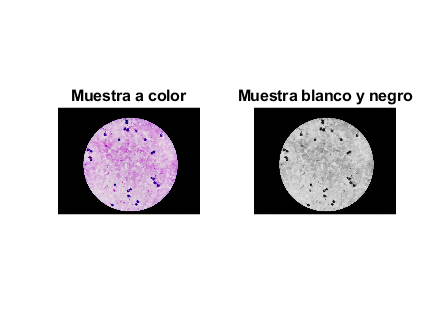

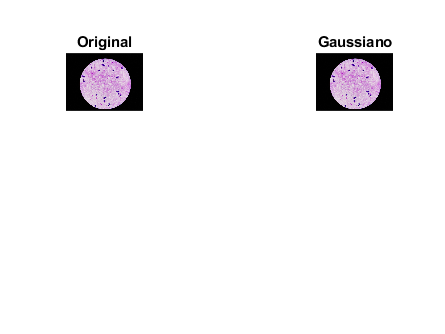

alto_Gauss = 3024

ancho_Gauss = 12096

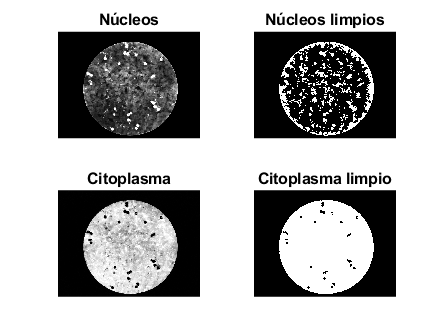

alto = 3024

ancho = 12096

table_dims = 1×3 table
    Var1    Var2    Var3
    ____    ____    ____

     31     4032    3024


parasite_table = 6×9 table
    parasite_data1    parasite_data2    parasite_data3    parasite_data4    parasite_data5    parasite_data6    parasite_data7    parasite_data8    parasite_data9
    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________

       {'0-1' }        {'Parasite'}     {'No_Comment'}      {'Circle'}          {'2'}          {'2675.35'}        {'566'   }       {'2678'   }        {'579.25'}  
       {'0-2' }        {'Parasite'}     {'No_Comment'}      {'Circle'}          {'2'}          {'2271.25'}        {'544.95'}       {'2260.65'}        {'555.55'}  
       {'0-3' 

wbc_table = 25×7 table
    wbc_data1         wbc_data2            wbc_data3       wbc_data4    wbc_data5     wbc_data6      wbc_data7 
    _________    ____________________    ______________    _________    _________    ___________    ___________

    {'0-10'}     {'White_Blood_Cell'}    {'No_Comment'}    {'Point'}      {'1'}      {'2226.95'}    {'664.7'  }
    {'0-11'}     {'White_Blood_Cell'}    {'No_Comment'}    {'Point'}      {'1'}      {'1972.9' }    {'613.9'  }
    {'0-12'}     {'White_Blood_Cell'}    {'No_Comment'}    {'Point'}      {'1'}      {'1953.85'}    {'372.6'  }
    {'0-13'}     {'White_Blood_Cell'}    {'No_Comment'}    {'Point'}      {'1'}      {'1941.15'}    {'436.1'  }
    {'0-14'}     {'White_Blood_Cell'}    {'No_Comment'}    {'Point

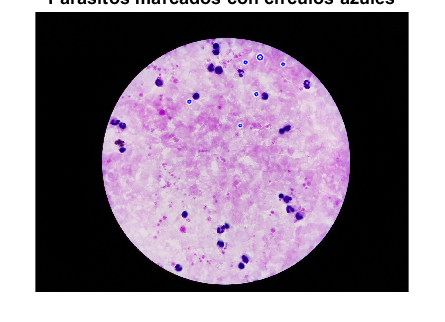

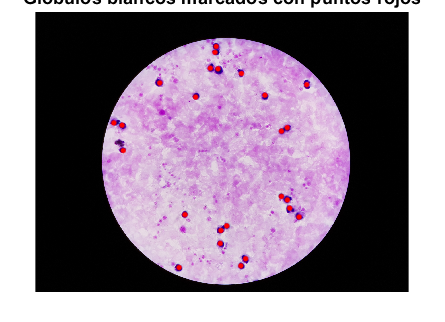

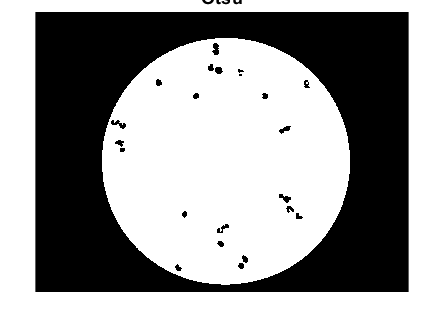

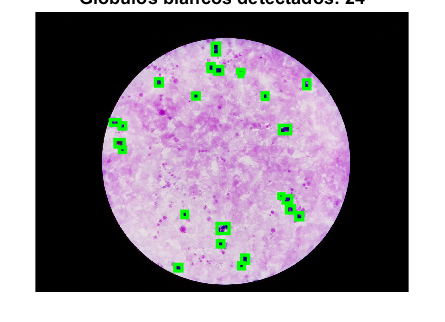

globulos_blancos = '24'

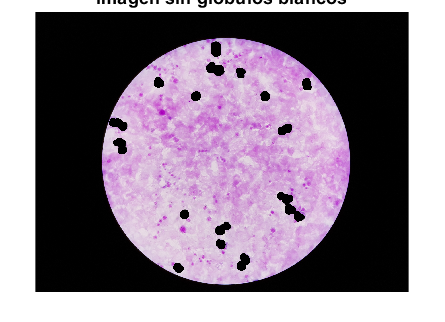

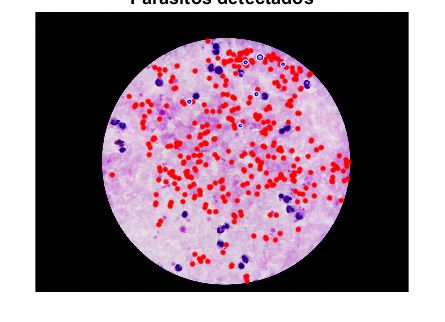

num_parasitos = 345

medianas_globulos = 1×9 table
    Num_Globulos    median_Area         median_BoundingBox         median_Eccentricity    median_Circularity    median_EquivDiameter    median_Solidity    median_Perimeter    median_MeanIntensity
    ____________    ___________    ____________________________    ___________________    __________________    ____________________    _______________    ________________    ____________________

         25             124        61.5    17.5      23      22          0.98748               0.35865                 12.565               0.81622             66.18                0.76645       


medianas_parasitos = 1×9 table
    Num_Parasitos    median_Area        median_BoundingBox        median_Eccentricity    median_Circularity    median_EquivDiameter    median_Solidity    median_Perimeter    median_MeanIntensity
    _____________    ___________    __________________________    ___________________    __________________    ____________________    _______________    ________________    ____________________

          6              426        11     0.5    90.5      39          0.96461               0.10427                 23.289               0.21195             226.03               0.75804       


clear all; close all; clc;

% === RUTAS ===
imageFolder = 'C:\Users\Xabier\OneDrive\Escritorio\Xabier\PBL 6\PF\TF5N_535';

% === ARCHIVOS DE IMAGEN ===
imageFiles = dir(fullfile(imageFolder, '*.jpg'));

**ANOTACIONES**

for i = 1:length(imageFiles)
    % Fitxategiaren izen osoa
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Irudia kargatu
    I=imread(filename);
    I_Gauss=imgaussfilt(I);
    % figure;
    % imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\Xabier\OneDrive\Escritorio\Xabier\PBL 6\PF\GT_updated\TF5N_535', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    % solo_parasitos = datos(strcmp(datos.Var2, 'Parasite'), :);
    % if ismember('Var8', datos.Properties.VariableNames) && ismember('Var9', datos.Properties.VariableNames)
    % x_parasitos = (solo_parasitos.Var6 + solo_parasitos.Var8) / 2;
    % y_parasitos = (solo_parasitos.Var7 + solo_parasitos.Var9) / 2;
    % plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 5, 'LineWidth', 0.5); % círculos rojos
    % leyenda_parasitos = true;
    % else
    % disp(['No se encontraron coordenadas de parásitos en la imagen: ', imageFiles(i).name]);
    % leyenda_parasitos = false;
    % end
    
    % ===== GLÓBULOS BLANCOS =====
    % solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    % x_wbc = solo_WBC.Var6;
    % y_wbc = solo_WBC.Var7;
    % plot(x_wbc, y_wbc, 'bo', 'MarkerSize', 5, 'LineWidth', 0.5);  % cruces azules
    % 
    % title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    % if leyenda_parasitos
    % legend('Parásitos', 'WBC');
    % else
    % legend('WBC');
    % end
    % hold off;
   
    % ===== ESTRUCTURAS CELULARES =====
    [alto, ancho, ~] = size(I);  % Obtiene las dimensiones de la imagen original
    [Nucleos_Limpios, Citoplasma_Limpios, Nucleos, Citoplasma] = extraerEstructurasCelulares(I_Gauss, alto, ancho);
    % figure; --> funciona pero peta
    % subplot(2,2,1); imshow(Nucleos); title('Núcleos');
    % subplot(2,2,2); imshow(Nucleos_Limpios); title('Núcleos limpios');
    % subplot(2,2,3); imshow(Citoplasma); title('Citoplasma');
    % subplot(2,2,4); imshow(Citoplasma_Limpios); title('Citoplasma limpio');
    
    % Detectar glóbulos blancos y eliminar de la imagen
    [num_globulos_blancos, mask_globulos, I_sin_globulos] = detectarGlobulosBlancos(I);

    % Detectar parásitos Otsu
    [num_parasitos, mask_parasitos, centros, radios] = detectarParasitos(I_sin_globulos);
    % Detectar parásitos Canny
    %[num_parasitos, mask_parasitos, centros, radios] = detectarParasitosCanny(I_sin_globulos);
    % Detectar parásitos Gabor
    %[num_parasitos, mask_parasitos, centros, radios] = detectarParasitosGabor(I_sin_globulos);
    % Detectar parásitos k-means
    %[num_parasitos, mask_parasitos, centros, radios] = detectarParasitosKMeans(I_sin_globulos);

    % === Confirmar candidatos a parásitos con validación morfológica y de color ===
    % Confirmar candidatos comparando con GT (posición)
    % píxeles, ajustable
    %25 para otsu
    %50+ para Canny
    %80+ para K-means
    %105+ para Gabor
    tolerancia = 25;
    centros_confirmados = confirmarParasitosPorProximidad(centros, datos, tolerancia);
    figure; imshow(I_Gauss); hold on;
    plot(centros_confirmados(:,1), centros_confirmados(:,2), 'r.', 'MarkerSize', 10);
    title(['Glóbulos blancos: ', num2str(num_globulos_blancos), ...
           ' | Parásitos confirmados (GT): ', num2str(size(centros_confirmados,1))]);
    hold off;

    % Mostrar resultados
    % figure; imshow(I); hold on;
    % plot(centros(:,1), centros(:,2), 'r.', 'MarkerSize', 10);
    % title(['Glóbulos blancos: ', num2str(num_globulos_blancos), ' |  Parásitos confirmados (GT): ', num2str(size(centros_confirmados,1))]);
    % hold off;
end

**EXTRAER ESTRUCTURAS CELULARES**

function [Nucleos_Limpios, Citoplasma_Limpios, Nucleos, Citoplasma] = extraerEstructurasCelulares(I_Gauss, alto, ancho)
    % Extrae núcleos y citoplasma de una imagen teñida con Giemsa

    % Separación de canales RGB
    R = I_Gauss(:,:,1);  
    G = I_Gauss(:,:,2);  
    B = I_Gauss(:,:,3);  

    % ===== NÚCLEOS =====
    Nucleos = 2*B - R - G;  % Enfatiza azul
    Nucleos = imadjust(Nucleos); 
    Nucleos_Binario = imbinarize(Nucleos, 'adaptive','Sensitivity', 0.3); 
    Nucleos_Limpios = imopen(Nucleos_Binario, strel('disk', 2));
    Nucleos_Limpios = imresize(Nucleos_Limpios, [alto, ancho]);

    % ===== CITOPLASMA =====
    Citoplasma = (R + 0.7*G) - 0.8*B;
    Citoplasma = imadjust(Citoplasma); 
    Citoplasma_Binario = imbinarize(Citoplasma, 0.08); 
    Citoplasma_Limpios = imclose(Citoplasma_Binario, strel('disk', 2));
    Citoplasma_Limpios = imresize(Citoplasma_Limpios, [alto, ancho]);
end

**DETECTAR GLOBULOS BLANCOS**

function [num_globulos_blancos, mask_globulos, I_sin_globulos] = detectarGlobulosBlancos(I_Gauss)
    % Convertir a escala de grises promedio
    A = mean(im2double(I_Gauss), 3);
    TO = graythresh(A);
    C = A > TO;

    % Invertir y limpiar
    BW_invert = ~C;
    BW_clean = bwareaopen(BW_invert, 45);

    % Etiquetar y filtrar regiones por tamaño
    [L, num] = bwlabel(BW_clean);
    stats = regionprops(L, 'Area');
    min_area = min([stats.Area]);
    max_area = max([stats.Area]);

    mask_globulos = false(size(BW_clean));
    for k = 1:num
        if stats(k).Area > min_area && stats(k).Area < max_area
            mask_globulos(L == k) = true;
        end
    end

    [~, num_globulos_blancos] = bwlabel(mask_globulos);

    % Dilatar y eliminar de la imagen
    se = strel('disk', 20);
    mascara_dilatada = imdilate(mask_globulos, se);
    %fondo_promedio = squeeze(mean(mean(I_Gauss(1:10, :, :), 1), 2));
    I_sin_globulos = I_Gauss;
    for c = 1:3
          canal = I_Gauss(:,:,c);
        I_sin_globulos(:,:,c) = regionfill(canal, mascara_dilatada);
    end
end

**1-METODO: OTSU**

function [num_parasitos, mask_parasitos, centros, radios] = detectarParasitos(I_sin_globulos)
    % Convertir a escala de grises y mejorar contraste
    I_gray = rgb2gray(I_sin_globulos);
    I_contrast = adapthisteq(I_gray);
    th = graythresh(I_contrast);
    BW = imbinarize(I_contrast, th);
    BW = imopen(~BW, strel('disk', 1));
    BW_clean = bwareaopen(BW, 25);

    % Etiquetar y filtrar regiones por tamaño
    [L, num] = bwlabel(BW_clean);
    stats = regionprops(L, 'Area', 'Centroid', 'BoundingBox', 'EquivDiameter');
    min_area = min([stats.Area]);
    max_area = max([stats.Area]);

    mask_parasitos = false(size(BW_clean));
    for k = 1:num
        if stats(k).Area > min_area && stats(k).Area < max_area
            mask_parasitos(L == k) = true;
        end
    end

    [~, num_parasitos] = bwlabel(mask_parasitos);
    stats_filtered = regionprops(mask_parasitos, 'Centroid', 'EquivDiameter');
    centros = cat(1, stats_filtered.Centroid);
    radios = [stats_filtered.EquivDiameter] / 2;
end

**2-METODO: CANNY**

function [num_parasitos, mask_parasitos, centros, radios] = detectarParasitosCanny(I_sin_globulos)
    % Detección de parásitos basada en bordes (Canny)

    % Convertir a escala de grises
    I_gray = rgb2gray(I_sin_globulos);
    
    % Filtrar con mediana para reducir ruido

    I_gauss = imgaussfilt(I_gray);
    I_filt = medfilt2(I_gauss,[3 3]);

    % Detectar bordes usando Canny
    BW_edges = edge(I_filt, 'Canny');

    % Cerrar bordes (morfología)
    BW_closed = imclose(BW_edges, strel('disk', 3));

 
    % Eliminar objetos pequeños
    BW_clean = bwareaopen(BW_closed, 300);

    % Etiquetar y filtrar regiones por tamaño
    [L, num] = bwlabel(BW_clean);
    stats = regionprops(L, 'Area', 'Centroid', 'EquivDiameter');
    min_area = min([stats.Area]);
    max_area = max([stats.Area]);

    mask_parasitos = false(size(BW_clean));
    centros = [];
    radios = [];

    for k = 1:num
        if stats(k).Area > min_area && stats(k).Area < max_area
            mask_parasitos(L == k) = true;
            centros = [centros; stats(k).Centroid];
            radios = [radios, stats(k).EquivDiameter / 2];
        end
    end

    num_parasitos = size(centros, 1);
end

**3-METODO: K-MEANS**

function [num_parasitos, mask_parasitos, centros, radios] = detectarParasitosKMeans(I_sin_globulos)

    % === 1. Segmentación con K-means ===
    rng(1);  % Asegura resultados reproducibles
    k = 3;   % Número de clusters
    [cluster_idx, ~] = imsegkmeans(I_sin_globulos, k);
    
    % === 2. Crear máscara para cada cluster ===
    masks = false([size(cluster_idx), k]);
    for i = 1:k
        masks(:,:,i) = cluster_idx == i;
        
    end
    
    % === 3. Analizar cada cluster para ver cuál parece contener los parásitos ===
    % Criterios: áreas pequeñas, formas redondeadas
    min_area = 50;
    max_area = 800;  % puedes ajustarlo según el tamaño del parásito

    best_mask = false(size(cluster_idx));
   
    centros = [];
    radios = [];

    for i = 1:k
        % Limpiar máscara
        mask = bwareaopen(masks(:,:,i), min_area);
        
        % Etiquetar componentes conectados
        [L, num] = bwlabel(mask);
        stats = regionprops(L, 'Area', 'Centroid', 'EquivDiameter');
        
        for j = 1:num
            area = stats(j).Area;
            if area >= min_area && area <= max_area
                best_mask = best_mask | (L == j);
                centros = [centros; stats(j).Centroid];
                radios = [radios; stats(j).EquivDiameter / 2];
            end
        end
    end

    % === 4. Salidas ===
    mask_parasitos = best_mask;
    num_parasitos = size(centros, 1);

end


**4-METODO: GABOR**

function [num_parasitos, mask_parasitos, centros, radios] = detectarParasitosGabor(I_sin_globulos)
    % Convertir a escala de grises
    Igray = rgb2gray(I_sin_globulos);
    Igray = im2double(Igray);

    % Crear banco de filtros Gabor
    wavelength = [2 4 8];     % Longitudes de onda
    orientation = 0:45:135;   % Orientaciones
    gaborBank = gabor(wavelength, orientation);

    % Aplicar filtros
    gaborMag = imgaborfilt(Igray, gaborBank);

    % Combinar respuestas: media de magnitudes
    gaborSum = mean(gaborMag, 3);

    % Normalizar
    gaborSum = mat2gray(gaborSum);

    % Segmentar con Otsu sobre la textura
    level = graythresh(gaborSum);
    mask = imbinarize(gaborSum, level);

    % Limpieza morfológica
    mask_clean = imopen(mask, strel('disk', 1));
    mask_clean = imclose(mask_clean, strel('disk', 2));
    mask_parasitos = bwareaopen(mask_clean, 30);
    mask_roi = crearMascaraCircular(size(mask_parasitos));  % Función auxiliar
    mask_parasitos = mask_parasitos & mask_roi;
    mask_parasitos = ~mask_parasitos;
    
    % Extraer características
    stats = regionprops(mask_parasitos, 'Centroid', 'EquivDiameter');

    centros = reshape([stats.Centroid], 2, []).';
    radios = [stats.EquivDiameter] / 2;
    num_parasitos = size(centros, 1);
end

function mask_circular = crearMascaraCircular(imSize)
    % imSize: tamaño de la imagen [filas, columnas]
    rows = imSize(1);
    cols = imSize(2);
    
    % Centro y radio
    [X, Y] = meshgrid(1:cols, 1:rows);
    centerX = round(cols / 2);
    centerY = round(rows / 2);
    radius = min(centerX, centerY) * 0.95;  % 95% del tamaño de la imagen

    % Crear máscara circular
    mask_circular = (X - centerX).^2 + (Y - centerY).^2 <= radius^2;
end


**CONFIRMAR CANDIDATOS**

function centros_confirmados = confirmarParasitosPorProximidad(centros_detectados, datos_gt, tolerancia)
    % Filtrar solo las anotaciones de tipo "Parasite"
    solo_parasitos = datos_gt(strcmp(datos_gt.Var2, 'Parasite'), :);

    % Verificar que las columnas necesarias existan
    if ~ismember('Var6', datos_gt.Properties.VariableNames) || ...
       ~ismember('Var8', datos_gt.Properties.VariableNames) || ...
       ~ismember('Var7', datos_gt.Properties.VariableNames) || ...
       ~ismember('Var9', datos_gt.Properties.VariableNames)
        warning('Las columnas necesarias no existen en el GT');
        centros_confirmados = [];
        return;
    end

    % Calcular los centros reales del GT: promedio entre esquina superior izquierda y esquina inferior derecha
    x_gt = (solo_parasitos.Var6 + solo_parasitos.Var8) / 2;
    y_gt = (solo_parasitos.Var7 + solo_parasitos.Var9) / 2;
    centros_gt = [x_gt, y_gt];

    % Inicializar lista de centros confirmados
    centros_confirmados = [];

    for i = 1:size(centros_detectados, 1)
        centro = centros_detectados(i, :);

        % Calcular distancia euclidiana a cada centro del GT
        distancias = sqrt(sum((centros_gt - centro).^2, 2));

        % Confirmar si hay alguna anotación dentro del radio de tolerancia
        if any(distancias < tolerancia)
            centros_confirmados = [centros_confirmados; centro];
        end
    end
end


